indigoData = readtable('all_data.xlsx');
indigoData = indigoData(strcmp(indigoData.Scoring, 'Loewe'),:);
dataFiles = indigoData.Filename(~indigoData.EcoliModelExclusive);

valMethod = 'cv';
K = 5;
standardize = '';
modelType = 2;
input_type = 2;

for i = 2:length(dataFiles)
    testFile = dataFiles{i};
    trainingData = dataFiles([1:i-1 i+1:end]);
    indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,modelType,input_type);
    [stats,averages,overview] = analyze(indigoSummary);
    save(saveIndigo(indigoSummary))
end

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 44.713215 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed time is 4

Results for ecoli_mg1655_chandrasekaran_2016

resultsTable = 5×11 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         35         0.49272     0.0029547    0.45714        0.57143              0.33333                0.2             

averagesTable = 11×1 table
                               Value  
                              ________

    Interactions                  34.2
    R (rank)                   0.37192
    P value                   0.051505
    Accuracy                    0.4679
    Absolute error             0.55546
    Precision (synergy)        0.43333
    Recall (synergy)              0.32
    Precision (antagonism)     0.71333
    Recall (antagonism)        0.24562
    AUC - ROC (synergy)         0.3472
    AUC - ROC (antagonism)     0.61278


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                     171
    R (rank)                     0.38004
    P value                   2.9462e-07
    Accuracy                     0.46784
    Absolute error               0.55556
    Precision (synergy)          0.42857
    Recall (synergy)             0.28571
    Precision (antagonism)       0.71429
    Recall (antagonism)           0.2381
    AUC - ROC (synergy)          0.36698
    AUC - ROC (antagonism)       0.61481


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 45.412756 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed time 

Results for s_aureus_chandrasekaran_2016

resultsTable = 5×11 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         9          -0.13333    0.74354    0.33333        0.66667                0.5                      1                 

averagesTable = 11×1 table
                               Value  
                              ________

    Interactions                     9
    R (rank)                  0.043333
    P value                    0.68018
    Accuracy                   0.46667
    Absolute error             0.62222
    Precision (synergy)            0.7
    Recall (synergy)           0.63333
    Precision (antagonism)     0.33333
    Recall (antagonism)           0.14
    AUC - ROC (synergy)        0.30675
    AUC - ROC (antagonism)      0.5725


overviewTable = 11×1 table
                               Value 
                              _______

    Interactions                   45
    R (rank)                  0.23477
    P value                   0.12058
    Accuracy                  0.46667
    Absolute error            0.62222
    Precision (synergy)         0.625
    Recall (synergy)              0.5
    Precision (antagonism)      0.375
    Recall (antagonism)       0.16667
    AUC - ROC (synergy)       0.39429
    AUC - ROC (antagonism)    0.57613


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 46.005255 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed time i

Results for mtb_h37rv_chandrasekaran_2016

resultsTable = 5×11 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         4           0.7746         0.5      0.75           0.25                   0.5                    1                 

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                  4.6
    R (rank)                  0.70459
    P value                   0.40667
    Accuracy                     0.75
    Absolute error               0.25
    Precision (synergy)       0.83333
    Recall (synergy)          0.86667
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)          0.15
    AUC - ROC (antagonism)        NaN


overviewTable = 11×1 table
                                Value  
                              _________

    Interactions                     23
    R (rank)                     0.6228
    P value                   0.0015029
    Accuracy                    0.73913
    Absolute error              0.26087
    Precision (synergy)             0.8
    Recall (synergy)                0.8
    Precision (antagonism)          NaN
    Recall (antagonism)               0
    AUC - ROC (synergy)         0.17692
    AUC - ROC (antagonism)       0.7381


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 45.437439 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed time 

Results for ecoli_mc4100_loewe_russ_2018

resultsTable = 5×11 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         16         0.57353      0.022358       0.75           0.25                  1                  0.5             

averagesTable = 11×1 table
                               Value  
                              ________

    Interactions                    16
    R (rank)                   0.49941
    P value                   0.076113
    Accuracy                    0.7125
    Absolute error                0.35
    Precision (synergy)            0.3
    Recall (synergy)               NaN
    Precision (antagonism)     0.94333
    Recall (antagonism)        0.75282
    AUC - ROC (synergy)            NaN
    AUC - ROC (antagonism)     0.77436


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                      80
    R (rank)                      0.5545
    P value                   9.4671e-08
    Accuracy                      0.7125
    Absolute error                  0.35
    Precision (synergy)             0.25
    Recall (synergy)                 0.5
    Precision (antagonism)       0.94545
    Recall (antagonism)          0.75362
    AUC - ROC (synergy)          0.10855
    AUC - ROC (antagonism)       0.74769


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 45.534045 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed t

Results for ecoli_mg1655_fatsis_2020

resultsTable = 5×11 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         3              1       0.33333    0.66667        0.33333                NaN                  NaN                   

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                  2.8
    R (rank)                      0.8
    P value                   0.73333
    Accuracy                      0.8
    Absolute error                0.2
    Precision (synergy)           NaN
    Recall (synergy)              NaN
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)           NaN
    AUC - ROC (antagonism)        NaN


overviewTable = 11×1 table
                               Value  
                              ________

    Interactions                    14
    R (rank)                   0.63727
    P value                   0.014232
    Accuracy                   0.78571
    Absolute error             0.21429
    Precision (synergy)            NaN
    Recall (synergy)                 0
    Precision (antagonism)         NaN
    Recall (antagonism)              0
    AUC - ROC (synergy)            0.5
    AUC - ROC (antagonism)         0.5


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 44.775994 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed ti

Results for ecoli_bw25113_ocampo_2014

resultsTable = 5×11 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         30         0.41567     0.022344        0.7        0.33333                  NaN                 0                 

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                   30
    R (rank)                  0.30708
    P value                   0.17329
    Accuracy                     0.62
    Absolute error               0.42
    Precision (synergy)           NaN
    Recall (synergy)              0.2
    Precision (antagonism)    0.70632
    Recall (antagonism)       0.82401
    AUC - ROC (synergy)       0.31466
    AUC - ROC (antagonism)    0.63355


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                     150
    R (rank)                     0.29877
    P value                   0.00020422
    Accuracy                        0.62
    Absolute error                  0.42
    Precision (synergy)              0.2
    Recall (synergy)            0.083333
    Precision (antagonism)       0.71171
    Recall (antagonism)          0.83158
    AUC - ROC (synergy)          0.36685
    AUC - ROC (antagonism)       0.63254


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 48.090190 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed

Results for a_baumannii_cokol_2018

resultsTable = 5×11 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         9           0.22037     0.57477    0.44444        0.55556              0.33333                 0.25              

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                    9
    R (rank)                  0.30417
    P value                   0.47966
    Accuracy                  0.42222
    Absolute error            0.66667
    Precision (synergy)       0.76667
    Recall (synergy)          0.34714
    Precision (antagonism)        0.3
    Recall (antagonism)           0.3
    AUC - ROC (synergy)       0.33667
    AUC - ROC (antagonism)        0.6


overviewTable = 11×1 table
                               Value 
                              _______

    Interactions                   45
    R (rank)                  0.22511
    P value                   0.13708
    Accuracy                  0.42222
    Absolute error            0.66667
    Precision (synergy)          0.75
    Recall (synergy)          0.34615
    Precision (antagonism)       0.25
    Recall (antagonism)       0.33333
    AUC - ROC (synergy)       0.36842
    AUC - ROC (antagonism)    0.61325


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 48.267849 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed t

Results for mtb_yilancioglu_2019_mtb

resultsTable = 5×11 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         21             0.2      0.38301     0.7619        0.47619              0.33333              0.66667              

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                   21
    R (rank)                   0.3174
    P value                   0.20914
    Accuracy                  0.77143
    Absolute error            0.45714
    Precision (synergy)          0.63
    Recall (synergy)          0.54762
    Precision (antagonism)    0.82461
    Recall (antagonism)       0.87175
    AUC - ROC (synergy)       0.29032
    AUC - ROC (antagonism)    0.70968


overviewTable = 11×1 table
                               Value  
                              ________

    Interactions                   105
    R (rank)                   0.28432
    P value                   0.003288
    Accuracy                   0.77143
    Absolute error             0.45714
    Precision (synergy)        0.61538
    Recall (synergy)           0.53333
    Precision (antagonism)     0.82278
    Recall (antagonism)        0.86667
    AUC - ROC (synergy)            0.3
    AUC - ROC (antagonism)         0.7


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 48.838892 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed

Results for mtb_h37rv_1_nicole_mtb

Index exceeds the number of array elements (4).

Error in internal.stats.corrSpearman>pvalSpearman (line 246)
        p(t) = tailProb(2*D(t)+1); % bins at half integers, starting at zero

Error in internal.stats.corrSpearman (line 162)
                pval = pvalSpearman(tail,D,meanD,

K=3;
for i = 10:length(dataFiles)
    testFile = dataFiles{i};
    trainingData = dataFiles([1:i-1 i+1:end]);
    indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,modelType,input_type);
    [stats,averages,overview] = analyze(indigoSummary);
    save(saveIndigo(indigoSummary))
end

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 49.504252 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed

Results for mtb_h37rv_1_nicole_mtb

resultsTable = 3×11 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         3              -0.5          1    0.66667        0.33333                NaN                    0                   

averagesTable = 11×1 table
                               Value  
                              ________

    Interactions                     3
    R (rank)                  -0.62201
    P value                    0.88889
    Accuracy                   0.77778
    Absolute error             0.22222
    Precision (synergy)            NaN
    Recall (synergy)               NaN
    Precision (antagonism)         NaN
    Recall (antagonism)            NaN
    AUC - ROC (synergy)            NaN
    AUC - ROC (antagonism)         NaN


overviewTable = 11×1 table
                               Value  
                              ________

    Interactions                     9
    R (rank)                  -0.78658
    P value                   0.016931
    Accuracy                   0.77778
    Absolute error             0.22222
    Precision (synergy)            NaN
    Recall (synergy)                 0
    Precision (antagonism)         NaN
    Recall (antagonism)            NaN
    AUC - ROC (synergy)            0.5
    AUC - ROC (antagonism)         NaN


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 48.438122 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed

Results for mtb_h37rv_2_nicole_mtb

resultsTable = 3×11 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         6          0.98561     0.0055556    0.83333        0.16667                NaN                  NaN             

averagesTable = 11×1 table
                               Value  
                              ________

    Interactions                     6
    R (rank)                   0.94645
    P value                   0.016667
    Accuracy                   0.88889
    Absolute error             0.11111
    Precision (synergy)            NaN
    Recall (synergy)               NaN
    Precision (antagonism)         NaN
    Recall (antagonism)            NaN
    AUC - ROC (synergy)            NaN
    AUC - ROC (antagonism)         NaN


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                      18
    R (rank)                     0.93816
    P value                   8.8461e-09
    Accuracy                     0.88889
    Absolute error               0.11111
    Precision (synergy)              NaN
    Recall (synergy)                 NaN
    Precision (antagonism)           NaN
    Recall (antagonism)                0
    AUC - ROC (synergy)              NaN
    AUC - ROC (antagonism)           0.5


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 49.227370 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed

Results for mtb_h37rv_3_nicole_mtb

resultsTable = 3×11 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         4              0           1         0.75           0.25                 0                   NaN                   

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions               3.6667
    R (rank)                  0.13333
    P value                   0.91667
    Accuracy                  0.72222
    Absolute error            0.27778
    Precision (synergy)             0
    Recall (synergy)              NaN
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)           NaN
    AUC - ROC (antagonism)        NaN


overviewTable = 11×1 table
                               Value 
                              _______

    Interactions                   11
    R (rank)                  0.15894
    P value                   0.64065
    Accuracy                  0.72727
    Absolute error            0.27273
    Precision (synergy)             0
    Recall (synergy)              NaN
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)           NaN
    AUC - ROC (antagonism)        NaN


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 49.395503 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed

Results for m_abscessus_nicole_mtb

Index exceeds the number of array elements (4).

Error in internal.stats.corrSpearman>pvalSpearman (line 246)
        p(t) = tailProb(2*D(t)+1); % bins at half integers, starting at zero

Error in internal.stats.corrSpearman (line 162)
                pval = pvalSpearman(tail,D,meanD,

K = 2;

testFile = dataFiles{13};
trainingData = dataFiles([1:13-1 13+1:end]);
indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,modelType,input_type);

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 49.217604 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed

[stats,averages,overview] = analyze(indigoSummary);

Results for m_abscessus_nicole_mtb

resultsTable = 2×11 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         4            -0.4       0.75          0.5            0.5                 0                     0                   

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                  3.5
    R (rank)                     0.05
    P value                     0.875
    Accuracy                  0.58333
    Absolute error            0.41667
    Precision (synergy)             0
    Recall (synergy)              NaN
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)           NaN
    AUC - ROC (antagonism)        NaN


overviewTable = 11×1 table
                               Value  
                              ________

    Interactions                     7
    R (rank)                  -0.10911
    P value                    0.82381
    Accuracy                   0.57143
    Absolute error             0.42857
    Precision (synergy)              0
    Recall (synergy)                 0
    Precision (antagonism)         NaN
    Recall (antagonism)            NaN
    AUC - ROC (synergy)        0.66667
    AUC - ROC (antagonism)         NaN


save(saveIndigo(indigoSummary))

K = 5;
testFile = dataFiles{14};
trainingData = dataFiles([1:14-1 14+1:end]);
indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,modelType,input_type);

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 49.795501 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed

[stats,averages,overview] = analyze(indigoSummary);

Results for m_smegmatis_nicole_mtb

resultsTable = 5×11 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         5             0.9      0.083333      0.8            0.2                  NaN                      0              

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                    5
    R (rank)                     0.66
    P value                   0.23333
    Accuracy                      0.6
    Absolute error                0.4
    Precision (synergy)           NaN
    Recall (synergy)          0.41667
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)         0.325
    AUC - ROC (antagonism)        NaN


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                      25
    R (rank)                     0.66255
    P value                   0.00030786
    Accuracy                         0.6
    Absolute error                   0.4
    Precision (synergy)          0.83333
    Recall (synergy)             0.41667
    Precision (antagonism)             0
    Recall (antagonism)              NaN
    AUC - ROC (synergy)          0.28526
    AUC - ROC (antagonism)           NaN


save(saveIndigo(indigoSummary))

valMethod = 'cv';
K = 5;
standardize = 'standardized';
modelType = 2;
input_type = 2;

for i = 2:length(dataFiles)
    testFile = dataFiles{i};
    trainingData = dataFiles([1:i-1 i+1:end]);
    indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,modelType,input_type);
    [stats,averages,overview] = analyze(indigoSummary);
    save(saveIndigo(indigoSummary))
end

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 46.240662 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed time is 4

Results for ecoli_mg1655_chandrasekaran_2016

resultsTable = 5×11 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         34         0.35218       0.041731    0.52941            0.5              0.66667              0.42857        

averagesTable = 11×1 table
                                Value  
                              _________

    Interactions                     34
    R (rank)                     0.5863
    P value                   0.0086149
    Accuracy                    0.59412
    Absolute error              0.41176
    Precision (synergy)         0.71429
    Recall (synergy)            0.47974
    Precision (antagonism)      0.93333
    Recall (antagonism)            0.43
    AUC - ROC (synergy)          0.2737
    AUC - ROC (antagonism)      0.78667


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                     170
    R (rank)                     0.59592
    P value                   1.0121e-17
    Accuracy                     0.59412
    Absolute error               0.41176
    Precision (synergy)          0.73333
    Recall (synergy)             0.49254
    Precision (antagonism)       0.88889
    Recall (antagonism)          0.42105
    AUC - ROC (synergy)          0.26764
    AUC - ROC (antagonism)       0.78648


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 46.991039 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed time 

Results for s_aureus_chandrasekaran_2016

resultsTable = 5×11 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         9              0.4      0.29119    0.44444        0.66667              0.42857                 0.75              

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                    9
    R (rank)                      0.3
    P value                   0.33218
    Accuracy                  0.57778
    Absolute error            0.46667
    Precision (synergy)       0.57857
    Recall (synergy)          0.81667
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)       0.35024
    AUC - ROC (antagonism)        NaN


overviewTable = 11×1 table
                               Value  
                              ________

    Interactions                    45
    R (rank)                   0.30838
    P value                   0.039302
    Accuracy                   0.57778
    Absolute error             0.46667
    Precision (synergy)        0.57143
    Recall (synergy)            0.7619
    Precision (antagonism)         NaN
    Recall (antagonism)              0
    AUC - ROC (synergy)        0.36905
    AUC - ROC (antagonism)     0.56707


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 47.414813 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed time i

Results for mtb_h37rv_chandrasekaran_2016

resultsTable = 5×11 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         5          0.35355       0.8        0.8            0.2                  0.5                    1                   

averagesTable = 11×1 table
                              Value
                              _____

    Interactions               4.8 
    R (rank)                   NaN 
    P value                    NaN 
    Accuracy                  0.84 
    Absolute error            0.16 
    Precision (synergy)        NaN 
    Recall (synergy)           NaN 
    Precision (antagonism)     NaN 
    Recall (antagonism)        NaN 
    AUC - ROC (synergy)        NaN 
    AUC - ROC (antagonism)     NaN 


overviewTable = 11×1 table
                                Value  
                              _________

    Interactions                     24
    R (rank)                    0.68034
    P value                   0.0002541
    Accuracy                    0.83333
    Absolute error              0.16667
    Precision (synergy)             0.8
    Recall (synergy)            0.66667
    Precision (antagonism)          NaN
    Recall (antagonism)               0
    AUC - ROC (synergy)         0.19444
    AUC - ROC (antagonism)       0.6087


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 45.649191 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed time 

Results for ecoli_mc4100_loewe_russ_2018

resultsTable = 5×11 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         16         0.51471       0.043661      0.375         0.6875                 0.4                  0.5         

averagesTable = 11×1 table
                               Value  
                              ________

    Interactions                    16
    R (rank)                   0.59353
    P value                   0.077782
    Accuracy                    0.5875
    Absolute error              0.4625
    Precision (synergy)          0.805
    Recall (synergy)             0.605
    Precision (antagonism)     0.74429
    Recall (antagonism)         0.6654
    AUC - ROC (synergy)        0.17145
    AUC - ROC (antagonism)     0.78511


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                      80
    R (rank)                     0.67321
    P value                   7.8504e-12
    Accuracy                      0.5875
    Absolute error                0.4625
    Precision (synergy)             0.75
    Recall (synergy)             0.62069
    Precision (antagonism)       0.72727
    Recall (antagonism)          0.68571
    AUC - ROC (synergy)          0.16362
    AUC - ROC (antagonism)       0.79683


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 46.350534 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed t

Results for ecoli_mg1655_fatsis_2020

resultsTable = 5×11 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         3               1      0.33333          1              0                  1                    1                   

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                  2.6
    R (rank)                      0.6
    P value                   0.86667
    Accuracy                  0.83333
    Absolute error            0.16667
    Precision (synergy)           NaN
    Recall (synergy)              NaN
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)           NaN
    AUC - ROC (antagonism)        NaN


overviewTable = 11×1 table
                               Value 
                              _______

    Interactions                   13
    R (rank)                  0.35759
    P value                    0.2303
    Accuracy                  0.84615
    Absolute error            0.15385
    Precision (synergy)             1
    Recall (synergy)              0.5
    Precision (antagonism)        NaN
    Recall (antagonism)             0
    AUC - ROC (synergy)          0.25
    AUC - ROC (antagonism)    0.54167


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 65.392515 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed ti

Results for ecoli_bw25113_ocampo_2014

resultsTable = 5×11 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         30         0.12249       0.51905    0.46667        0.66667              0.55556                  0.5           

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                 29.6
    R (rank)                  0.44483
    P value                   0.10853
    Accuracy                   0.4731
    Absolute error            0.56023
    Precision (synergy)       0.62659
    Recall (synergy)          0.44916
    Precision (antagonism)    0.71667
    Recall (antagonism)       0.40631
    AUC - ROC (synergy)       0.27818
    AUC - ROC (antagonism)    0.72329


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                     148
    R (rank)                     0.44698
    P value                   1.2343e-08
    Accuracy                     0.47297
    Absolute error               0.56081
    Precision (synergy)          0.62162
    Recall (synergy)             0.43396
    Precision (antagonism)       0.68966
    Recall (antagonism)              0.4
    AUC - ROC (synergy)          0.28133
    AUC - ROC (antagonism)       0.71878


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 50.123341 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed

Results for a_baumannii_cokol_2018

resultsTable = 5×11 table
                Interactions    R (rank)     P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    _________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         9          -0.033333    0.94839    0.33333         1.2222                  0.6                  0.5              

averagesTable = 11×1 table
                               Value  
                              ________

    Interactions                     9
    R (rank)                  0.085802
    P value                    0.74696
    Accuracy                   0.42222
    Absolute error             0.95556
    Precision (synergy)        0.65333
    Recall (synergy)           0.50571
    Precision (antagonism)     0.39667
    Recall (antagonism)            0.4
    AUC - ROC (synergy)        0.43476
    AUC - ROC (antagonism)     0.54381


overviewTable = 11×1 table
                               Value 
                              _______

    Interactions                   45
    R (rank)                  0.11385
    P value                   0.45648
    Accuracy                  0.42222
    Absolute error            0.95556
    Precision (synergy)       0.64706
    Recall (synergy)             0.44
    Precision (antagonism)    0.38889
    Recall (antagonism)       0.36842
    AUC - ROC (synergy)         0.486
    AUC - ROC (antagonism)    0.51518


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 46.811463 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed t

Results for mtb_yilancioglu_2019_mtb

resultsTable = 5×11 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         21         0.41039      0.065797    0.90476        0.19048                    1              0.71429           

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                   21
    R (rank)                  0.39403
    P value                   0.13109
    Accuracy                  0.74286
    Absolute error            0.51429
    Precision (synergy)       0.65238
    Recall (synergy)          0.55786
    Precision (antagonism)    0.80754
    Recall (antagonism)       0.82385
    AUC - ROC (synergy)       0.30915
    AUC - ROC (antagonism)    0.69085


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                     105
    R (rank)                     0.38018
    P value                   6.3238e-05
    Accuracy                     0.74286
    Absolute error               0.51429
    Precision (synergy)          0.56667
    Recall (synergy)             0.54839
    Precision (antagonism)       0.81333
    Recall (antagonism)          0.82432
    AUC - ROC (synergy)          0.31364
    AUC - ROC (antagonism)       0.68636


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 49.517843 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed

Results for mtb_h37rv_1_nicole_mtb

Index exceeds the number of array elements (4).

Error in internal.stats.corrSpearman>pvalSpearman (line 246)
        p(t) = tailProb(2*D(t)+1); % bins at half integers, starting at zero

Error in internal.stats.corrSpearman (line 162)
                pval = pvalSpearman(tail,D,meanD,

K = 2;
for i = 10:13
    testFile = dataFiles{i};
    trainingData = dataFiles([1:i-1 i+1:end]);
    indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,modelType,input_type);
    [stats,averages,overview] = analyze(indigoSummary);
    save(saveIndigo(indigoSummary))
end

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 46.158227 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed

Results for mtb_h37rv_1_nicole_mtb

resultsTable = 2×11 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         5          -0.87208    0.066667      0.8            0.2                  NaN                    0                

averagesTable = 11×1 table
                               Value  
                              ________

    Interactions                     5
    R (rank)                  -0.76948
    P value                    0.16667
    Accuracy                       0.9
    Absolute error                 0.1
    Precision (synergy)            NaN
    Recall (synergy)               NaN
    Precision (antagonism)         NaN
    Recall (antagonism)            NaN
    AUC - ROC (synergy)            NaN
    AUC - ROC (antagonism)         NaN


overviewTable = 11×1 table
                                Value  
                              _________

    Interactions                     10
    R (rank)                   -0.79931
    P value                   0.0055266
    Accuracy                        0.9
    Absolute error                  0.1
    Precision (synergy)             NaN
    Recall (synergy)                  0
    Precision (antagonism)          NaN
    Recall (antagonism)             NaN
    AUC - ROC (synergy)             0.5
    AUC - ROC (antagonism)          NaN


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 47.828670 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed

Results for mtb_h37rv_2_nicole_mtb

resultsTable = 2×11 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         9          0.67552       0.04828    0.77778        0.22222                NaN                  NaN             

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                    9
    R (rank)                  0.75243
    P value                   0.02791
    Accuracy                  0.72222
    Absolute error            0.27778
    Precision (synergy)           NaN
    Recall (synergy)              NaN
    Precision (antagonism)        NaN
    Recall (antagonism)             0
    AUC - ROC (synergy)           NaN
    AUC - ROC (antagonism)        0.5


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                      18
    R (rank)                     0.77215
    P value                   0.00017354
    Accuracy                     0.72222
    Absolute error               0.27778
    Precision (synergy)              NaN
    Recall (synergy)                 NaN
    Precision (antagonism)           NaN
    Recall (antagonism)                0
    AUC - ROC (synergy)              NaN
    AUC - ROC (antagonism)           0.5


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 48.847232 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed

Results for mtb_h37rv_3_nicole_mtb

resultsTable = 2×11 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         6           0.46382    0.37222    0.83333        0.16667                 0                   NaN                   

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                    6
    R (rank)                  0.27477
    P value                   0.64583
    Accuracy                     0.75
    Absolute error               0.25
    Precision (synergy)             0
    Recall (synergy)              NaN
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)           NaN
    AUC - ROC (antagonism)        NaN


overviewTable = 11×1 table
                               Value 
                              _______

    Interactions                   12
    R (rank)                  0.24427
    P value                    0.4442
    Accuracy                     0.75
    Absolute error               0.25
    Precision (synergy)             0
    Recall (synergy)                0
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)       0.59091
    AUC - ROC (antagonism)        NaN


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 47.246859 seconds.


Index exceeds the number of array elements (80).

Error in internal.stats.corrSpearman>pvalSpearman (line 246)
        p(t) = tailProb(2*D(t)+1); % bins at half integers, starting at zero

Error in internal.stats.corrSpearman (line 162)
                pval = pvalSpearman(tail,D,meanD

K = 2;
testFile = dataFiles{13};
trainingData = dataFiles([1:13-1 13+1:end]);
indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,modelType,input_type);

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_smegmatis_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 47.096040 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed

Results for m_abscessus_nicole_mtb

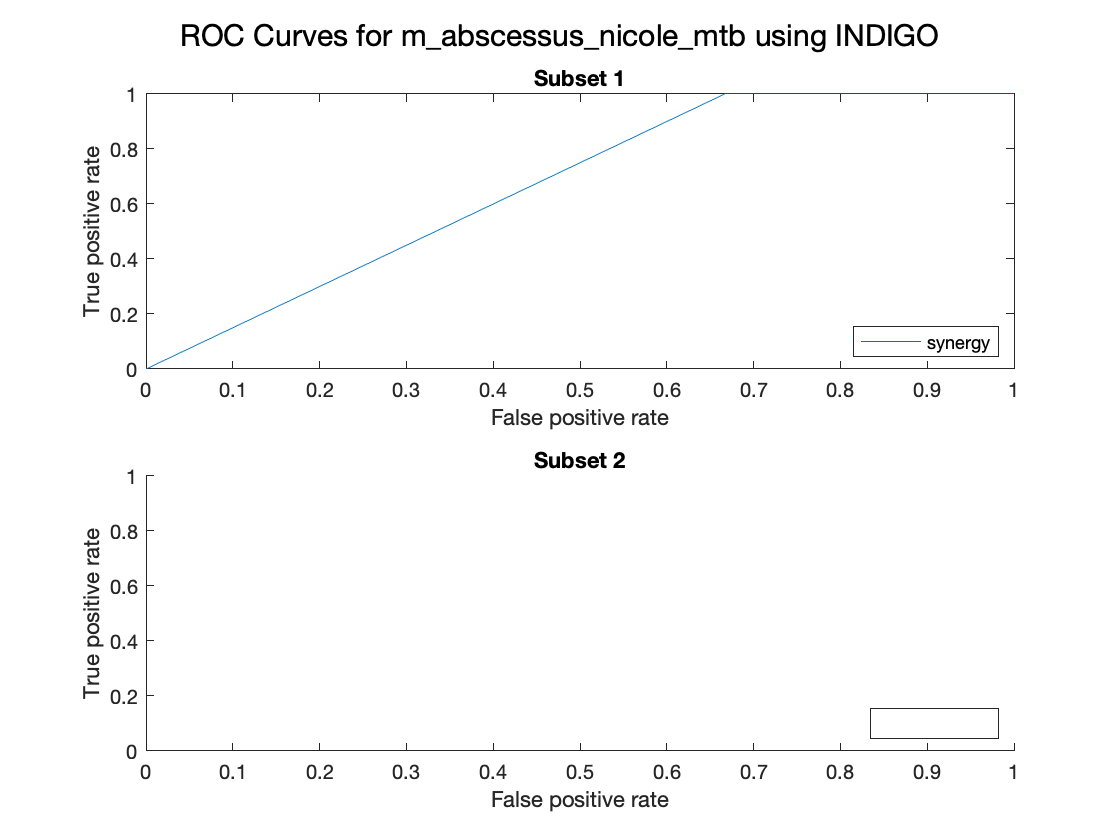

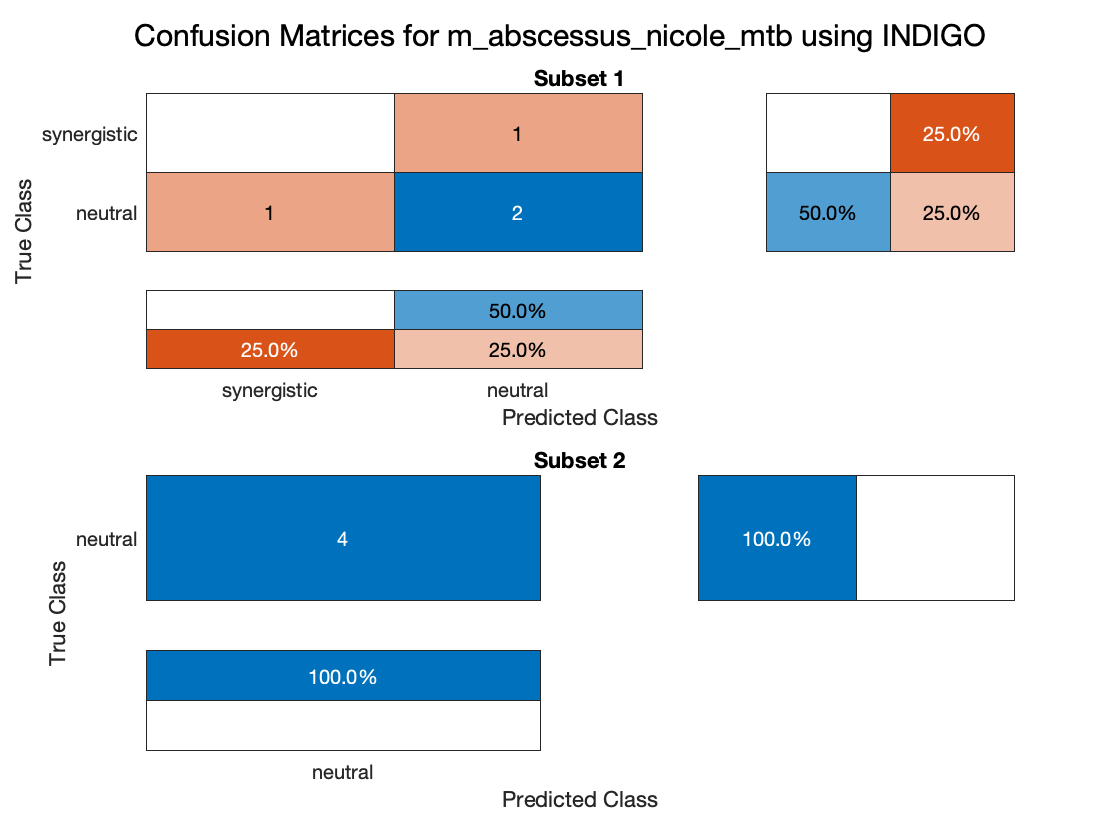

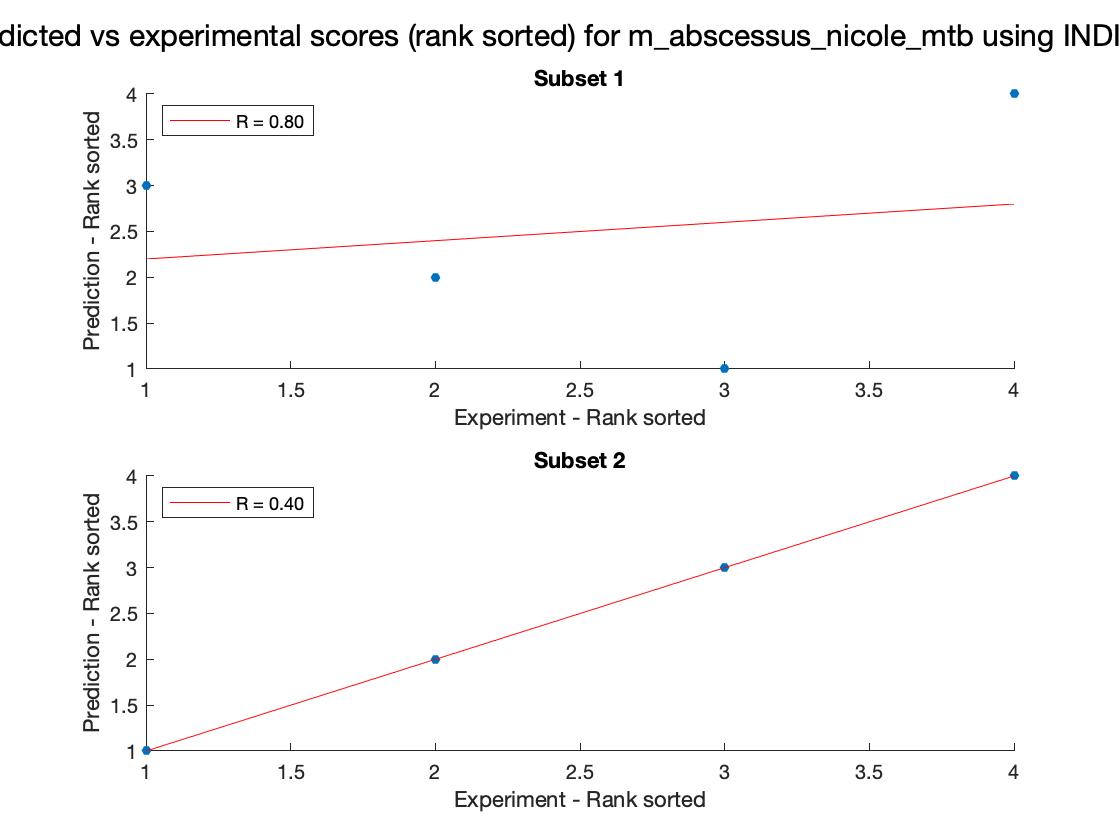

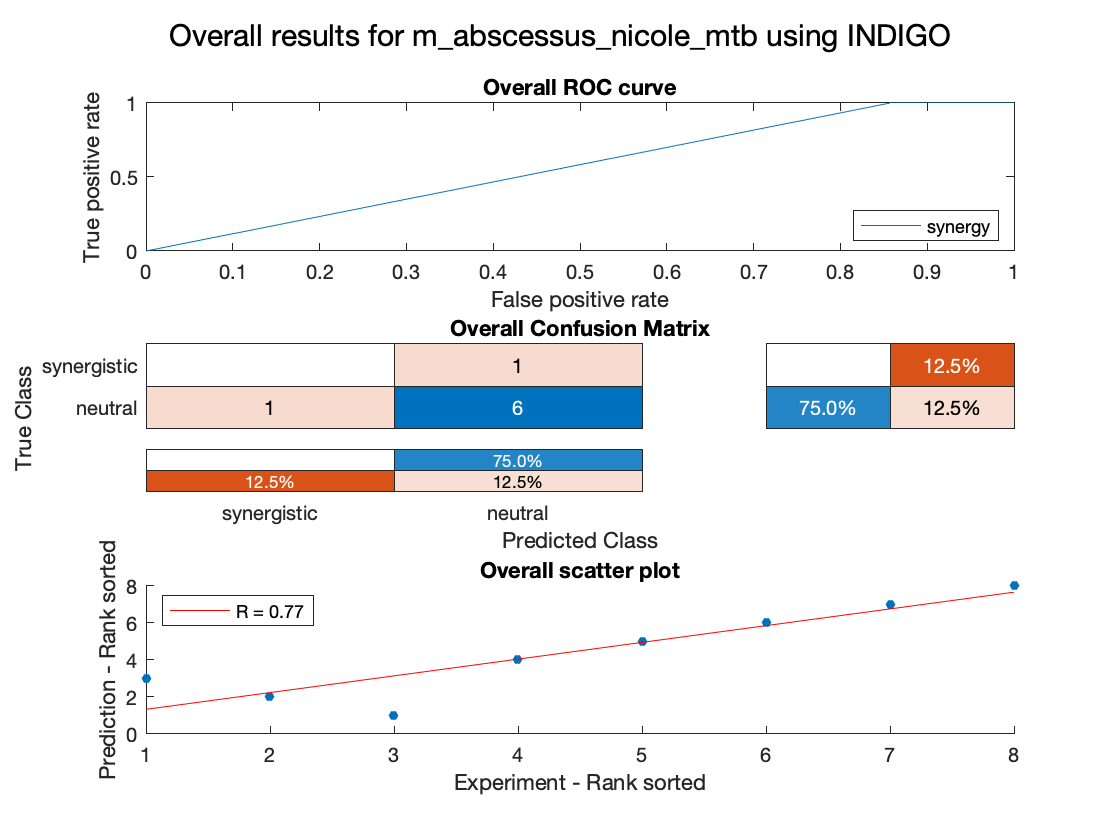

resultsTable = 2×11 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         4            0.8       0.33333      0.5            0.5                    0                    0                   

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                    4
    R (rank)                      0.6
    P value                   0.54167
    Accuracy                     0.75
    Absolute error               0.25
    Precision (synergy)           NaN
    Recall (synergy)              NaN
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)           NaN
    AUC - ROC (antagonism)        NaN


overviewTable = 11×1 table
                               Value  
                              ________

    Interactions                     8
    R (rank)                   0.77114
    P value                   0.031944
    Accuracy                      0.75
    Absolute error                0.25
    Precision (synergy)              0
    Recall (synergy)                 0
    Precision (antagonism)         NaN
    Recall (antagonism)            NaN
    AUC - ROC (synergy)        0.57143
    AUC - ROC (antagonism)         NaN


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

K = 5;

testFile = dataFiles{14};
trainingData = dataFiles([1:14-1 14+1:end]);
indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,modelType,input_type);

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training data
Adding a_baumannii_cokol_2018.xlsx to training data
Adding mtb_yilancioglu_2019_mtb.xlsx to training data
Adding mtb_h37rv_1_nicole_mtb.xlsx to training data
Adding mtb_h37rv_2_nicole_mtb.xlsx to training data
Adding mtb_h37rv_3_nicole_mtb.xlsx to training data
Adding m_abscessus_nicole_mtb.xlsx to training data
Run 1
Elapsed time is 45.517775 seconds.
INDIGO predictions subset 1 complete!
Run 2
Elapsed

Results for m_smegmatis_nicole_mtb

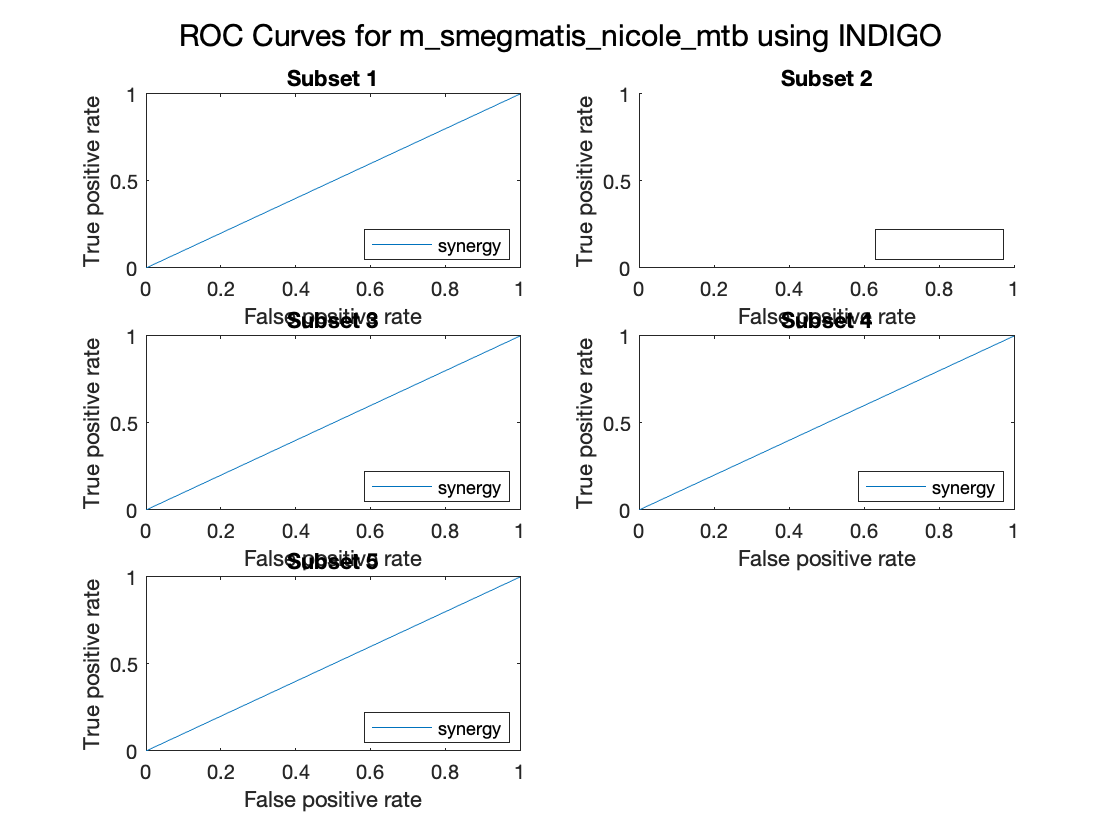

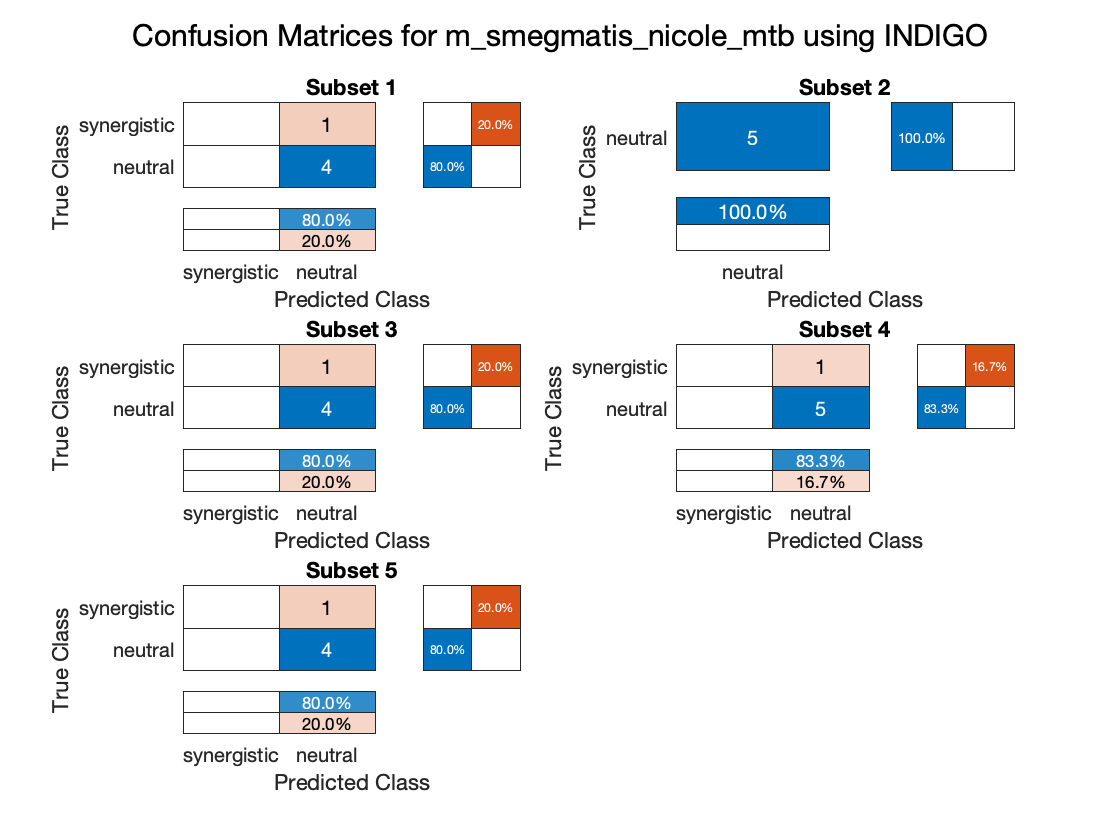

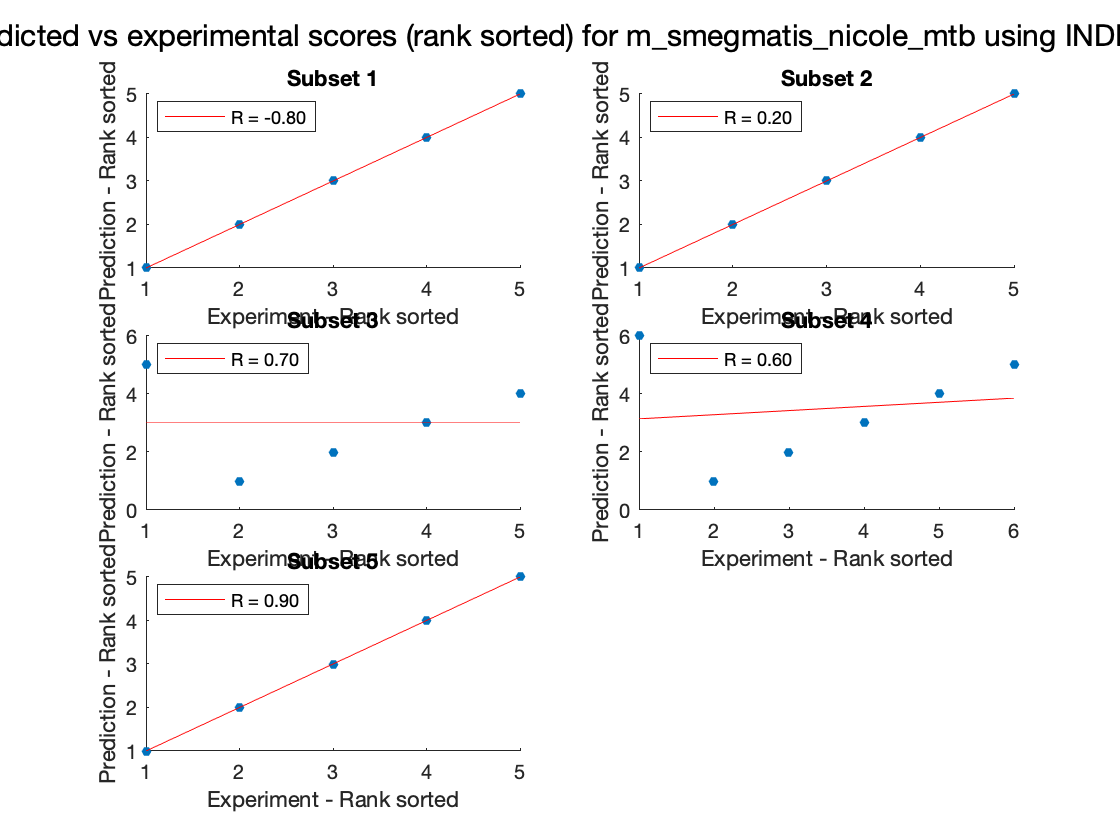

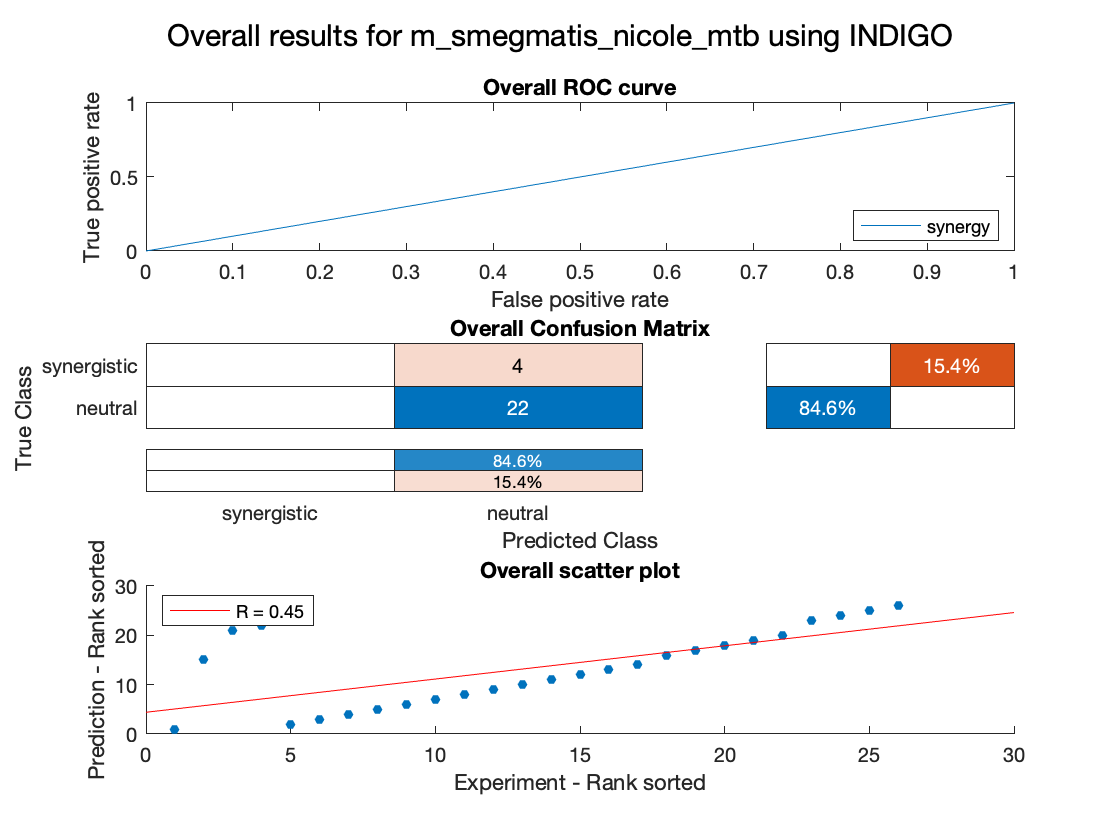

resultsTable = 5×11 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         5            -0.8       0.13333        0.8            0.2                NaN                    0                

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                  5.2
    R (rank)                     0.32
    P value                     0.295
    Accuracy                  0.84667
    Absolute error            0.15333
    Precision (synergy)           NaN
    Recall (synergy)              NaN
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)           NaN
    AUC - ROC (antagonism)        NaN


overviewTable = 11×1 table
                               Value  
                              ________

    Interactions                    26
    R (rank)                   0.44727
    P value                   0.021963
    Accuracy                   0.84615
    Absolute error             0.15385
    Precision (synergy)            NaN
    Recall (synergy)                 0
    Precision (antagonism)         NaN
    Recall (antagonism)            NaN
    AUC - ROC (synergy)            0.5
    AUC - ROC (antagonism)         NaN


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))